# METODO DEL PUNTO FIJO

clc, clear;
format long g;
syms x;

**INGRESAR EL X DE DATO INFERIOR:**

Lim_inf = 0;

**INGRESAR EL X DE DATO SUPERIOR:**

Lim_sup = pi/2;

**INGRESAR LA TOLERACIA:**

Tol     = 0.0001;

**INGRESAR EL NUMERO DE ITERACIONES:**

Num_it  = 20;

**INGRESAR LA ECUACÍON x=g(x):**

f_x= cos(x);

**=========================================================================================================================**

**=========================================================================================================================**

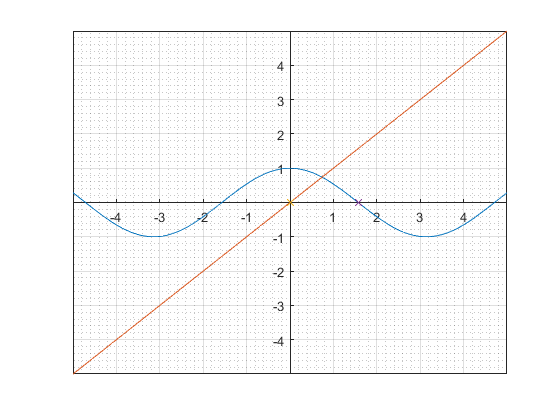

% n=[1 2];
% a_n=[1 2];
% b_n=[1 2];
% p_n=[1 2];
% f_n=[1 2];
n=[1 2];
x_0=[1 2];
g_x=[1 2];
error_=[0 2];
y=x;

fplot(f_x);
hold on;
fplot(y);
plot(Lim_inf,0,'x');
plot(Lim_sup,0,'x');
hold off;
grid on;
grid minor;
ax = gca;
ax.XAxisLocation = 'origin';
ax.YAxisLocation = 'origin';

f= @(x) eval(f_x);
i=1;
p_0=Lim_inf+(Lim_sup-Lim_inf)/2;
while(i<Num_it)
    p=f(p_0);
    
    n(i)=i;
    x_0(i)= p_0;
    g_x(i)=f(p_0);
    error_(i)= p-p_0;
    
    if((p_0==f(p_0)))
        disp(p);
        break;
    else
        p_0=p;
    end
    i=i+1;
end


tabla=[n' x_0' g_x' error_'];
NUM_IT=n';
x_=x_0';
g__x=g_x';
error__=error_';
Resultados = table(NUM_IT,x_,g__x,error__)

Resultados = 19×4 table
    NUM_IT           x_                  g__x                  error__       
    ______    _________________    _________________    _____________________
       1      0.785398163397448    0.707106781186548      -0.0782913822109007
       2      0.707106781186548     0.76024459707563       0.0531378158890825
       3       0.76024459707563    0.724667480889126      -0.0355771161865038
       4      0.724667480889126    0.748719885789484        0.024052404900358
       5      0.748719885789484    0.732560844592242      -0.0161590411972424
       6      0.732560844592242    0.743464211315294       0.0109033667230518
       7      0.743464211315294    0.736128256500852      -0.0073359548144416
       8      0.736128256500852     0.74107368708371      0.00494543058285823
       9       0.74107368708371    0.737744158992575     -0.

xlswrite('RESULTADOS.xlsx',tabla)